# Fixed Wing Control Design

Define parameters:

clc
clear

parameters

Va0=P.Va0;
g=P.g;
rho=1.225;

beta0=0;
alpha0=0;

Prop_R = sqrt(P.Sprop/pi);
Prop_diam = 2*Prop_R;

Fuel_density = (775.0 + 840.0) / 2; % density of Jet A-1 fuel (kg/m^3)
%https://code7700.com/fuel_density.htm

Fuel_L = P.Fuel_Cap_L /2 ; % amount of fuel in L -> half a tank
W_fuel_half = (Fuel_L/1000)*Fuel_density*P.gravity; % weight of gas in N

Weight = (P.m * P.gravity) + W_fuel_half;

AR = P.b/P.c;
K = 1 / (pi*P.e*AR);

dyn_pressure = (1/2)*rho*(Va0)^2;
CL = Weight / (dyn_pressure*P.S);
CD = P.C_Do + K*CL^2;

% physical parameters of airframe

m=P.m;
Ixx=P.Ixx;
Iyy=P.Iyy;
Izz=P.Izz;
Ixz=P.Ixz;
S=P.S;
b=P.b;
c=P.c;
Sprop=P.Sprop;
e=P.e;
Omega_max=P.OmegaMax_RPM; % rad/s
FuelCapacity=P.Fuel_Cap_L; % L

% Longitudinal

Cl0=P.C_Lo;
CD0=P.C_Do;
Cm0=P.C_mo;
Clalpha=P.C_Lalpha;
CDalpha=P.C_Dalpha;
Cmalpha=P.C_malpha;
Clq=P.C_Lq;
CDq=P.C_Dq;
Cmq=P.C_mq;
Cldelta_e=P.C_Ldelta_e;
CDdelta_e=P.C_Ddelta_e_;
Cmdelta_e=P.C_mdelta_e_;
epsilon=P.C_Epsilon;

% Lateral

CY0=P.C_Yo;
Cl0=P.C_lo;
Cn0=P.C_no;
CYbeta=P.C_Ybeta;
Clbeta=P.C_lbeta;
Cnbeta=P.C_nbeta;
CYp=P.C_Yp;
Clp=P.C_lp;
Cnp=P.C_np;
CYr=P.C_Yr;
Clr=P.C_lr;
Cnr=P.C_nr;
CYdelta_a=P.C_Ydelta_a;
Cldelta_a=P.C_ldelta_a;
Cndelta_a=P.C_ndelta_a;
CYdelta_r=P.C_Ydelta_r;
Cldelta_r=P.C_ldelta_r;
Cndelta_r=P.C_ndelta_r;

% compute inertial constants

K = Ixx*Izz-Ixz^2;
k1 = Ixz*(Ixx-Iyy+Izz)/K;
k2 = (Izz*(Izz-Iyy)+Ixz^2)/K;
k3 = Izz/K;
k4 = Ixz/K;
k5 = (Izz-Ixx)/Iyy;
k6 = Ixz/Iyy;
k7 = ((Ixx-Iyy)*Ixx+Ixz^2)/K;
k8 = Ixx/K;

% Additional Coefficients

Cp0=k3*Cl0+k4*Cn0;
Cpbeta=k3*Clbeta+k4*Cnbeta;
Cpp=k3*Clp+k4*Cnp;
Cpr=k3*Clr+k4*Cnr;
Cpdelta_a=k3*Cldelta_a+k4*Cndelta_a;
Cpdelta_r=k3*Cldelta_r+k4*Cndelta_r;
Cr0=k4*Cl0+k8*Cn0;
Crbeta=k4*Clbeta+k8*Cnbeta;
Crp=k4*Clp+k8*Cnp;
Crr=k4*Clr+k8*Cnr;
Crdelta_a=k4*Cldelta_a+k8*Cndelta_a;
Crdelta_r=k4*Cldelta_r+k8*Cndelta_r;

CX0=-CD0*cos(alpha0)+CL*sin(alpha0);
CXalpha=0;
CXq=-CDq*cos(alpha0)+Clq*sin(alpha0);
CXdelta_e=-CDdelta_e*cos(alpha0)+Cldelta_e*sin(alpha0);
CZ0=-CD0*sin(alpha0)-CL*cos(alpha0);
CZalpha=0;
CZq=-CDq*sin(alpha0)-Clq*cos(alpha0);
CZdelta_e=-CDdelta_e*sin(alpha0)-Cldelta_e*cos(alpha0);

% Initial Conditions

pn0=P.pn0;
pe0=P.pe0;
pd0=P.pd0;
u0=P.u0;
v0=P.v0;
w0=P.w0;
phi0=P.phi0;
theta0=P.theta0;
psi0=P.psi0;
p0=P.p0;
q0=P.q0;
r0=P.r0;
delta_e0=P.delta_e0;
delta_a0=P.delta_a0;
delta_r0=P.delta_r0;
delta_t0=P.delta_t0;

% Longitudinal Aerodynamic Derivatives

Xu=(u0*rho*S)/m*(CX0+CXalpha*alpha0+CXdelta_e*delta_e0)-(rho*S*w0*CXalpha)/(2*m)+(rho*S*c*CXq*u0*q0)/(4*m*Va0)-(rho*Sprop*u0)/m;
Xw=-q0+(w0*rho*S)/m*(CX0+CXalpha*alpha0+CXdelta_e*delta_e0)+(rho*S*c*CXq*w0*q0)/(4*m*Va0)+(rho*S*CXalpha*u0)/(2*m)-(rho*Sprop*w0)/m;
Xq=-w0+(rho*Va0*S*CXq*c)/(4*m);
Xdelta_e=(rho*Va0^2*S*CXdelta_e)/(2*m);
Xdelta_t=(rho*Sprop*delta_t0^2)/m;

Zu=q0+(u0*rho*S)/m*(CZ0+CZalpha*alpha0+CZdelta_e*delta_e0)-(rho*S*w0*CZalpha)/(2*m)+(rho*S*c*CZq*u0*q0)/(4*m*Va0);
Zw=(w0*rho*S)/m*(CZ0+CZalpha*alpha0+CZdelta_e*delta_e0)+(rho*S*c*CZq*w0*q0)/(4*m*Va0)+(rho*S*CZalpha*u0)/(2*m);
Zq=u0+(rho*Va0*S*CZq*c)/(4*m);
Zdelta_e=(rho*Va0^2*S*CZdelta_e)/(2*m);

Mu=(u0*rho*S*c)/Iyy*(Cm0+Cmalpha*alpha0+Cmdelta_e*delta_e0)+(rho*S*c*Cmalpha*w0)/(2*Iyy)+(rho*S*c^2*Cmq*q0*u0)/(4*Iyy*Va0);
Mw=(w0*rho*S*c)/Iyy*(Cm0+Cmalpha*alpha0+Cmdelta_e*delta_e0)+(rho*S*c*Cmalpha*u0)/(2*Iyy)+(rho*S*c^2*Cmq*q0*w0)/(4*Iyy*Va0);
Mq=(rho*Va0*S*c^2*Cmq)/(4*Iyy);
Mdelta_e=(rho*Va0*2*S*c*Cmdelta_e)/(2*Iyy);

% Lateral Aerodynamic Derivatives

Yv=(rho*S*b*v0)/(4*m*Va0)*(CYp*p0+CYr*r0)+(rho*S*v0)/m*(CY0+CYbeta*beta0+CYdelta_a*delta_a0+CYdelta_r*delta_r0)+(rho*S*CYbeta)/(2*m)*sqrt(u0^2+w0^2);
Yp=w0+(rho*Va0*S*b)/(4*m)*CYp;
Yr=-u0+(rho*Va0*S*b)/(4*m)*CYdelta_r;
Ydelta_a=(rho*Va0^2*S)/(2*m)*CYdelta_a;
Ydelta_r=(rho*Va0^2*S)/(2*m)*CYdelta_r;

Lv=(rho*S*b^2*v0^2)/(4*Va0)*(Cpp*p0+Cpr*r0)+rho*S*b*v0*(Cp0+Cpbeta*beta0+Cpdelta_a*delta_a0+Cpdelta_r*delta_r0)+(rho*S*b*Cpbeta)/2*sqrt(u0^2+v0^2);
Lp=k1*q0+(rho*Va0*S*b^2)/4*Cpp;
Lr=-k2*q0+(rho*Va0*S*b^2)/4*Cpr;
Ldelta_a=(rho*Va0^2*S*b)/2*Cpdelta_a;
Ldelta_r=(rho*Va0^2*S*b)/2*Cpdelta_r;

Nv=(rho*S*b^2*v0^2)/(4*Va0)*(Crp*p0+Crr*r0)+rho*S*b*v0*(Cr0+Crbeta*beta0+Crdelta_a*delta_a0+Crdelta_r*delta_r0)+(rho*S*b*Crbeta)/2*sqrt(u0^2+v0^2);
Np=k7*q0+(rho*Va0*S*b^2)/4*Crp;
Nr=-k1*q0+(rho*Va0*S*b^2)/4*Crr;
Ndelta_a=(rho*Va0^2*S*b)/2*Crdelta_a;
Ndelta_r=(rho*Va0^2*S*b)/2*Crdelta_r;


**State-Space Design with LQR**

Longitudinal Model:

A_long=[Xu Xw Xq -g*cos(theta0) 0;...
    Zu Zw Zq -g*sin(theta0) 0;...
    Mu Mw Mq 0 0;
    0 0 1 0 0;
    sin(theta0) -cos(theta0) 0 u0*cos(theta0)+w0*sin(theta0) 0]

A_long =    -0.1990         0         0   -9.8100         0
   -1.5310         0   15.0000         0         0
   -0.0404   -0.3213   -0.2891         0         0
         0         0    1.0000         0         0
         0   -1.0000         0   15.0000         0



B_long=[Xdelta_e 1; Zdelta_e 0; Mdelta_e 0; 0 0; 0 0]

B_long =          0    1.0000
    2.0212         0
   -0.8456         0
         0         0
         0         0



A1=[A_long B_long zeros(5,2);...
    zeros(2,5) [-10 0 0 0; 0 -1/3.5 0 0];...
    -1 zeros(1,8);...
    zeros(1,4) -1 zeros(1,4)];

B1=[zeros(5,2); [10 0; 0 1/3.5]; 0 0; 0 0]

B1 =          0         0
         0         0
         0         0
         0         0
         0         0
   10.0000         0
         0    0.2857
         0         0
         0         0



C1=eye(9);

F1=zeros(9,2);

E1=[zeros(7,2); 1 0; 0 1];

% Select Q and R

Q1=30;
R1=3000;

% Open loop system

sys1=ss(A1,B1,C1,F1);

% Design controller

[Y1,P1,CLP1]=lqr(sys1,Q1,R1);
% [X1,S]=linsolve(C1',Y1');
% K1=X1';
K1=Y1

K1 =     1.0300   -0.1425   -2.5987    0.6474    0.4469    0.1793    1.1490   -0.0485   -0.0875
    0.4492   -0.1925   -0.9018    2.1431    0.2644    0.0328    0.6835    0.0875   -0.0485


K1_ss=K1(:,1:5)

K1_ss =     1.0300   -0.1425   -2.5987    0.6474    0.4469
    0.4492   -0.1925   -0.9018    2.1431    0.2644


K1_J=K1(:,6:7)

K1_J =     0.1793    1.1490
    0.0328    0.6835


K1_u=K1(:,8:9)

K1_u =    -0.0485   -0.0875
    0.0875   -0.0485


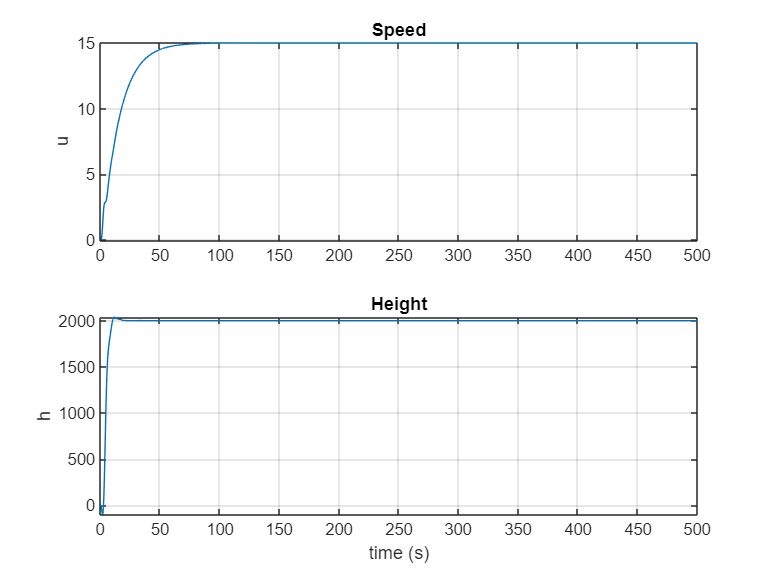


Long_ICs=[Va0; 0; 0; 0; -pd0];
%Long_ICs=[0; 0; 0; 0; 0];

A1_sim=A1(1:5,1:5);
B1_sim=B_long;
C1_sim=C1(1:5,1:5);
D1_sim=zeros(5,2);

% Closed loop system

Ac1=A1-B1*K1;
Bc1=E1-B1*K1*F1;
% Bc1=B1;

ss_closed1=ss(Ac1,Bc1,C1,F1);

% Simulation

amp1=stepDataOptions;
amp1.StepAmplitude=[15 2000];
t=0:0.01:500;
[y1,tt1,x1]=step(ss_closed1,t,amp1);
x1long=y1(:,1,1);
x2long=y1(:,5,2);

figure(2)
subplot(2,1,1)
plot(t,x1long)
grid
title('Speed');
ylabel('u');

subplot(2,1,2)
plot(t,x2long)
grid
title('Height');
xlabel('time (s)');
ylabel('h');

Lateral Model:

A_latr=[Yv Yp Yr g*cos(theta0)*cos(phi0) 0;...
    Lv Lp Lr 0 0;...
    Nv Np Nr 0 0;...
    0 1 cos(phi0)*tan(theta0) q0*cos(phi0)*tan(theta0)-r0*sin(phi0)*tan(theta0) 0;...
    0 0 cos(phi0)*sec(theta0) p0*cos(phi0)*sec(theta0)-r0*sin(phi0)*sec(theta0) 0]

A_latr =    -0.3668         0  -15.0921    9.8100         0
   -1.8445   -6.7094    3.0120         0         0
    1.9533   -0.1943   -4.0090         0         0
         0    1.0000         0         0         0
         0         0    1.0000         0         0



B_latr=[Ydelta_a Ydelta_r; Ldelta_a Ldelta_r; Ndelta_a Ndelta_r; 0 0; 0 0]

B_latr =          0   -0.9545
   22.6176   27.6471
    9.0346   -2.1004
         0         0
         0         0



A2=[A_latr B_latr zeros(5,2);...
    zeros(2,5) [-20.2 0 0 0; 0 -20.2 0 0];...
    zeros(1,3) -1 zeros(1,5);...
    zeros(1,4) -1 zeros(1,4)];

B2=[zeros(5,2); [20.2 0; 0 20.2]; 0 0; 0 0]

B2 =          0         0
         0         0
         0         0
         0         0
         0         0
   20.2000         0
         0   20.2000
         0         0
         0         0



C2=eye(9);

F2=zeros(9,2);

E2=[zeros(7,2); 1 0; 0 1];

% Select Q and R

Q2=1;
R2=0.1;

% Open loop system

sys2=ss(A2,B2,C2,F2);

% Design controller

[Y2,P2,CLP2]=lqr(sys2,Q2,R2);
% [X2,S]=linsolve(C2',Y2');
% K2=X2';
K2=Y2

K2 =    -1.2765    1.3361    4.2063    1.6096    9.9830    3.1987    0.3550    1.7663   -2.6230
    1.1063    2.3862   -2.5354    8.7138    3.2899    0.3550    3.2224   -2.6230   -1.7663


K2_ss=K2(:,1:5)

K2_ss =    -1.2765    1.3361    4.2063    1.6096    9.9830
    1.1063    2.3862   -2.5354    8.7138    3.2899


K2_J=K2(:,6:7)

K2_J =     3.1987    0.3550
    0.3550    3.2224


K2_u=K2(:,8:9)

K2_u =     1.7663   -2.6230
   -2.6230   -1.7663


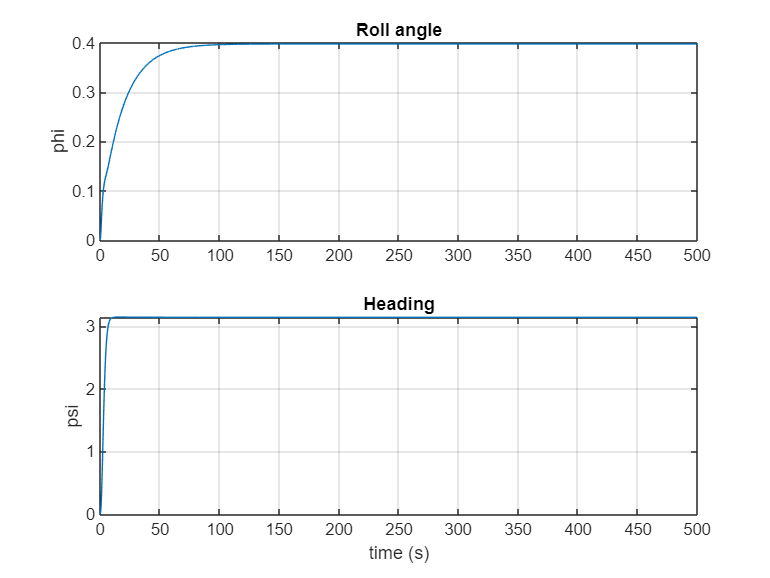


Latr_ICs=[0; 0; 0; 0; 0];

A2_sim=A2(1:5,1:5);
B2_sim=B_latr;
C2_sim=C2(1:5,1:5);
D2_sim=zeros(5,2);

% Closed loop system

Ac2=A2-B2*K2;
Bc2=E2-B2*K2*F2;
% Bc2=B2;

ss_closed2=ss(Ac2,Bc2,C2,F2);

% Simulation

amp2=stepDataOptions;
amp2.StepAmplitude=[0.398 pi];
t=0:0.01:500;
[y2,tt2,x2]=step(ss_closed2,t,amp2);
x1latr=y2(:,4,1);
x2latr=y2(:,5,2);

figure(3)
subplot(2,1,1)
plot(t,x1latr)
grid
title('Roll angle');
ylabel('phi');

subplot(2,1,2)
plot(t,x2latr)
grid
title('Heading');
xlabel('time (s)');
ylabel('psi');